## Edge detection using wavelet transformation  

### Sources

[https://www2.humusoft.cz/www/papers/tcb10/078_petrova.pdf](https://www2.humusoft.cz/www/papers/tcb10/078_petrova.pdf)

[https://www.mdpi.com/2076-3417/13/3/1837](https://www.mdpi.com/2076-3417/13/3/1837)

### Clear

clear all; clc;

### Single level wavelet

#### Edge detection

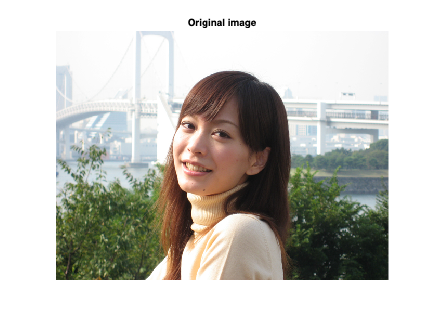

% Step 1: Read the image
img_path  ='img/cameraman.tif';
img_path  ='img/portrait_5.jpg';

original_image = imread(img_path);

imshow(original_image, [], 'InitialMagnification', 'fit'); 
title('Original image'); 


% Step 2: Convert the image to grayscale (if it's a color image)
if size(original_image, 3) == 3
    gray_image = rgb2gray(original_image);
else
    gray_image = original_image;
end

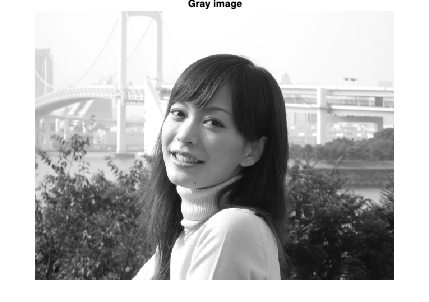

% Step 2: Perform a wavelet transform (e.g., using Haar wavelet)
wname = 'haar';
[cA, cH, cV, cD] = dwt2(gray_image, wname);

% Step 3: Replace approximation coefficients (LL) with zeros
cA = zeros(size(cA)); % Set all approximation coefficients to zeros
%cA = edge(cA, 'canny'); % Set all approximation coefficients to zeros

% Step 4: Reconstruct the modified image
rec_cA = idwt2(cA, cH, cV, cD, 'haar');

% Step 6: Display the results
imshow(gray_image); 
title('Gray image');

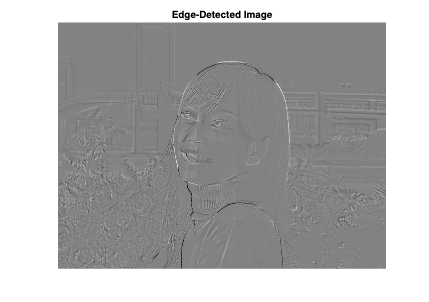


imshow(rec_cA, [], 'InitialMagnification', 'fit'); 
title('Edge-Detected Image'); 

### Multiple level wavelet

#### Wave transform

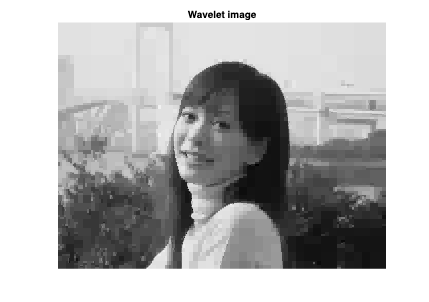

N = 10; % Set the number of levels
wname = 'haar';
[C,S] = wavedec2(gray_image, N, wname);

% Set the threshold value (adjust as needed)
w_threshold = 100;
C(abs(C) <= w_threshold) = 0;

cA = appcoef2(C,S, wname, N);
[cH ,cV, cD] = detcoef2('all', C, S, N);

wavelet_image = waverec2(C, S, wname);
imshow(wavelet_image, [], 'InitialMagnification', 'fit'); 
title('Wavelet image');

#### Edge detection

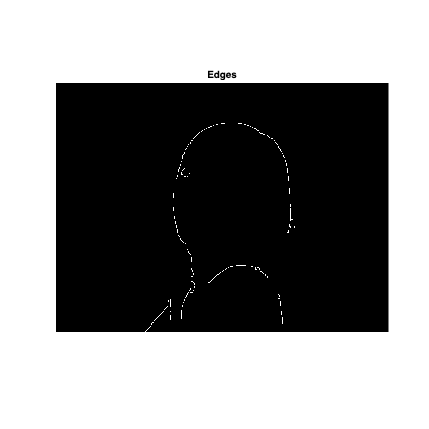

edge_threshold = 0.5;
edge_image = edge(wavelet_image,'Canny', edge_threshold);
my_fig = figure; imshow(edge_image, [], 'InitialMagnification', 'fit'); set(my_fig, 'Position', [0 0 1000 1000])
title('Edges');

#### Morphological operations

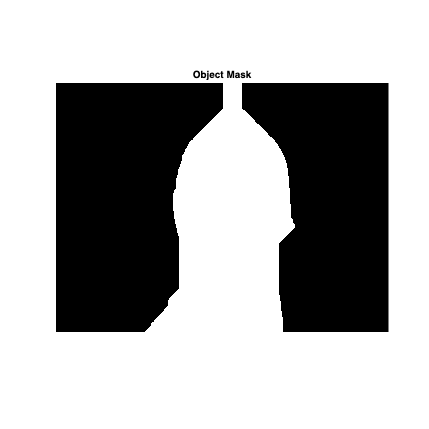

clf
% Define a structuring element (disk) for morphological operations
se = strel('disk', 110); % Adjust the size as needed

% Perform morphological dilation to connect edges
% Dilation is an operation that expands or thickens regions in a binary image.
% In this context, it is used to connect nearby edges or gaps in the edgeImage, which can help merge fragmented objects or regions.
dilated_image = imdilate(edge_image, se);

% Perform morphological erosion to refine the object mask
% rosion is an operation that shrinks or erodes regions in a binary image.
% In this context, it is used to refine the object mask by removing any noise 
% or small disconnected regions that may have been introduced during dilation.
object_mask = uint8(imerode(dilated_image, se));

% Invert the object mask to obtain the background mask
background_mask = uint8(~object_mask);

% Display the object mask and background mask
imshow(object_mask, [], 'InitialMagnification', 'fit');
title('Object Mask');

#### Extract mask

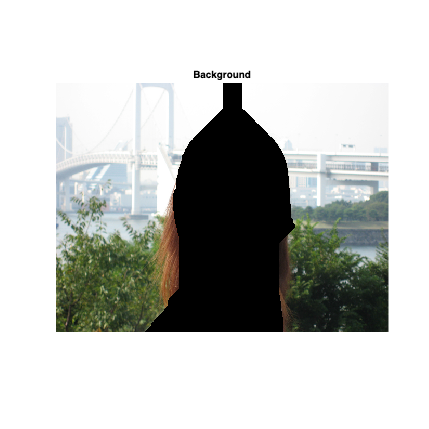

background = background_mask .* original_image;
object = object_mask .* original_image;

imshow(background, [], 'InitialMagnification', 'fit');
title('Background')

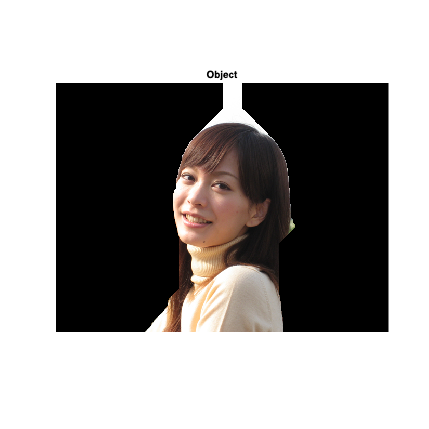


imshow(object, [], 'InitialMagnification', 'fit');
title('Object')

#### Background blur 

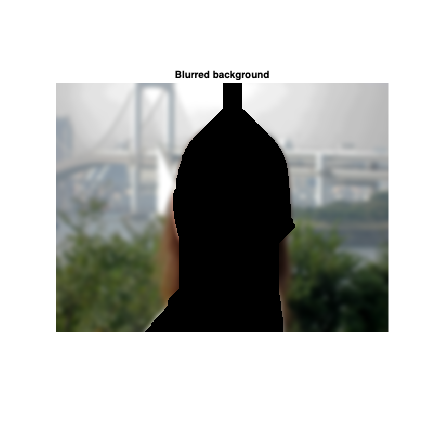

sigma = 5;
blurred_background = imgaussfilt(histeq(original_image), sigma) .* background_mask; 
imshow(blurred_background, [], 'InitialMagnification', 'fit');
title('Blurred background')

#### Object enhancement 

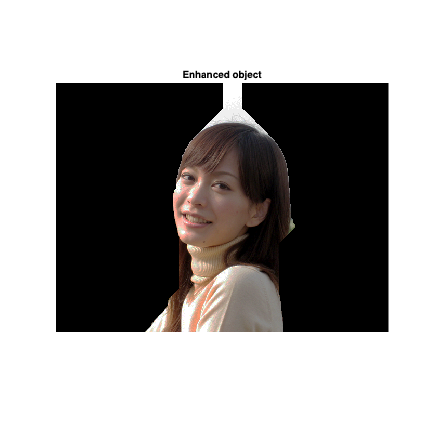

enhanced_object = histeq(original_image) .* object_mask; 
imshow(enhanced_object, [], 'InitialMagnification', 'fit');
title('Enhanced object')

#### Final results

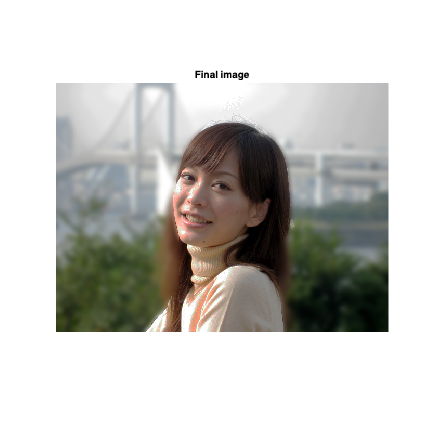

final_image = blurred_background + enhanced_object;
imshow(final_image, [], 'InitialMagnification', 'fit');
title('Final image')